% =========================================================================
% 3. FÁZIS: ÉLES TESZTELÉS (Self-Tuning Dual-Stage Deep Ensemble AI)
% =========================================================================
import casadi.*
disp('=== TESZTELÉS INDÍTVA: Klasszikus vs. Önhangoló Hibrid AI ===');

=== TESZTELÉS INDÍTVA: Klasszikus vs. Önhangoló Hibrid AI ===



if ~exist('ensemble_mean', 'var') || ~exist('ensemble_sigma', 'var')
    error('Hiba: Nem találom a hálózatokat!');
end
num_nets = length(ensemble_mean);

% Pálya (1 kör teszt)
egy_kor_pontjai = smooth_path(1:end-1, :); 
multi_lap_path = [egy_kor_pontjai; smooth_path(end, :)];
Ts = 0.1; V_target = 5; N = 10; 

% --- JAVÍTVA: Saját dist és t_path számítása 1 körre! ---
ds = sqrt(diff(multi_lap_path(:,1)).^2 + diff(multi_lap_path(:,2)).^2);
dist_test = [0; cumsum(ds)]; 
t_path_test = dist_test / V_target; 
t_sim_test = 0:Ts:t_path_test(end); 

X_ref = interp1(t_path_test, multi_lap_path(:,1), t_sim_test, 'linear', 'extrap');
Y_ref = interp1(t_path_test, multi_lap_path(:,2), t_sim_test, 'linear', 'extrap');
RefMatrix = [X_ref', Y_ref', [diff(X_ref)/Ts, 0]', [diff(Y_ref)/Ts, 0]'];

% Dinamika és LQR (Azonos a tanítóval!)
A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1]; B = [0 0; 0 0; Ts 0; 0 Ts];
K_lqr = dlqr(A, B, diag([50, 50, 5, 5]), diag([0.5, 0.5]));

% CasADi Felépítése Self-Tuning Paraméterrel
opti = casadi.Opti();
X = opti.variable(4, N+1); U = opti.variable(2, N);   
x0_param = opti.parameter(4, 1); ref_param = opti.parameter(4, N+1);      
w_nn_param = opti.parameter(4, 1); tube_uncertainty_param = opti.parameter(1, 1); 
q_mult_param = opti.parameter(1, 1); % SELF-TUNING SZORZÓ

Q_mpc_base = diag([100, 100, 0, 0]); R_mpc_base = diag([0.1, 0.1]);     
cost = 0; max_y_elteres = 2.0; 

for k = 1:N
    err = X(:, k) - ref_param(:, k);
    cost = cost + q_mult_param * (err' * Q_mpc_base * err) + U(:, k)' * R_mpc_base * U(:, k);
    opti.subject_to(X(:, k+1) == A * X(:, k) + B * U(:, k) + w_nn_param);
    akt_cs_szelesseg = max_y_elteres * (1.0 - tube_uncertainty_param);
    opti.subject_to( -akt_cs_szelesseg <= err(1:2) <= akt_cs_szelesseg );
end
cost = cost + q_mult_param * ((X(:, N+1) - ref_param(:, N+1))' * Q_mpc_base * (X(:, N+1) - ref_param(:, N+1)));
opti.minimize(cost); opti.subject_to(X(:, 1) == x0_param); opti.subject_to(-20 <= U <= 20); 
opti.solver('ipopt', struct('expand', true), struct('max_iter', 100, 'print_level', 0, 'acceptable_tol', 1e-6));

n_steps_test = length(t_sim_test) - N - 1;
rng(100); zaj_alap_test = randn(2, n_steps_test); 

history_cl = zeros(n_steps_test, 4); errors_cl = zeros(n_steps_test, 1);
history_ai = zeros(n_steps_test, 4); errors_ai = zeros(n_steps_test, 1);
tube_history = zeros(n_steps_test, 1); q_mult_history = zeros(n_steps_test, 1);

for mode = 1:2
    x_real = RefMatrix(1,:)'; z_nom = x_real; u_prev = [0; 0];
    szel_memoria = [0;0]; w_smoothed = [0; 0; 0; 0]; 
    x_hist1 = x_real; x_hist2 = x_real; % Csúszóablak pufferek
    
    for k = 1 : n_steps_test
        current_ref = RefMatrix(k : k+N, :)';
        if mode == 1
            w_becsult = [0; 0; 0; 0]; tightening_factor = 0.0; current_q_mult = 1.0; 
        else
            % 14 Elemű bemenet lekérdezése
            nn_input = dlarray([x_real; x_hist1; x_hist2; u_prev], 'CB'); 
            tippek_mean = zeros(4, num_nets); tippek_sigma = zeros(4, num_nets);
            for i = 1:num_nets
                tippek_mean(:, i) = double(extractdata(predict(ensemble_mean{i}, nn_input)));
                tippek_sigma(:, i) = double(extractdata(predict(ensemble_sigma{i}, nn_input)));
            end
            
            % --- VISSZAOSZTJUK A 100-AS SZORZÓT ÉS ABSZOLÚT ÉRTÉKET VESZÜNK ---
            w_zaj_mertek = abs(mean(tippek_sigma, 2)) / 100.0; 
            max_biz = max(w_zaj_mertek(1:2));
            w_raw = mean(tippek_mean, 2); 
            
            % --- NORMÁL HIPERPARAMÉTEREK ---
            % Visszaállítjuk az eredeti, kevésbé "túlfeszített" szorzókat
            alpha_ema = max(0.02, 0.9 - (max_biz * 10.0));
            w_smoothed = (1 - alpha_ema) * w_smoothed + alpha_ema * w_raw; 
            w_becsult = max(min(w_smoothed, 0.5), -0.5); 
            
            tightening_factor = min(0.85, max_biz * 20.0); 
            current_q_mult = min(exp(max_biz * 15.0), 15.0); 
            
            tube_history(k) = tightening_factor; 
            q_mult_history(k) = current_q_mult;
        end
        
        opti.set_value(x0_param, z_nom); opti.set_value(ref_param, current_ref);
        opti.set_value(w_nn_param, w_becsult); opti.set_value(tube_uncertainty_param, tightening_factor); 
        opti.set_value(q_mult_param, current_q_mult); 
        
        try, sol = opti.solve(); v_k_opt = sol.value(U(:, 1)); catch, v_k_opt = opti.debug.value(U(:, 1)); end
        
        u_k = max(min(v_k_opt - K_lqr * (x_real - z_nom), 50), -50); 
        
        % Fizika
        drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts; drag_y = -0.02 * x_real(4) * abs(x_real(4)) * Ts;
        spatial_x = 0.5 * sin(x_real(1)/15); spatial_y = 0.5 * cos(x_real(2)/15);
        zona_szorzo = 0.1 + 1.4 * (0.5 + 0.5 * tanh((x_real(1)-40)/5));
        szel_memoria(1) = 0.8 * szel_memoria(1) + zaj_alap_test(1, k)*0.4;
        szel_memoria(2) = 0.8 * szel_memoria(2) + zaj_alap_test(2, k)*0.4;
        w_k = [0; 0; (0.8*Ts) + drag_x + (spatial_x + szel_memoria(1))*zona_szorzo; 
                     (0.5*Ts) + drag_y + (spatial_y + szel_memoria(2))*zona_szorzo];
        
        x_real_new = A * x_real + B * u_k + w_k;
        z_nom = A * z_nom + B * v_k_opt + w_becsult; 
        
        % Csúszóablak frissítése
        x_hist2 = x_hist1; x_hist1 = x_real; u_prev = u_k; x_real = x_real_new;
        
        hiba = min(sqrt((smooth_path(:,1)-x_real(1)).^2 + (smooth_path(:,2)-x_real(2)).^2));
        if mode == 1, history_cl(k, :) = x_real'; errors_cl(k) = hiba; 
        else, history_ai(k, :) = x_real'; errors_ai(k) = hiba; end
    end
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  42.00us (  3.23us)        13
       nlp_g  |   1.00ms ( 76.92us) 142.00us ( 10.92us)        13
  nlp_grad_f  |        0 (       0)  84.00us (  6.00us)        14
  nlp_hess_l  |        0 (       0)  36.00us (  3.00us)        12
   nlp_jac_g  |        0 (       0)  65.00us (  4.64us)        14
       total  |  67.00ms ( 67.00ms)  65.87ms ( 65.87ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  30.00us (  2.50us)        12
       nlp_g  |        0 (       0)  86.00us (  7.17us)        12
  nlp_grad_f  |        0 (       0)  43.00us (  3.31us)        13
  nlp_hess_l  |        0 (       0)  30.00us (  2.73us)        11
   nlp_jac_g  |        0 (       0)  52.00us (  4.00us)        13
       total  |  29.00ms ( 29.00ms)  28.04ms ( 28.04ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp


disp('=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===');

=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===


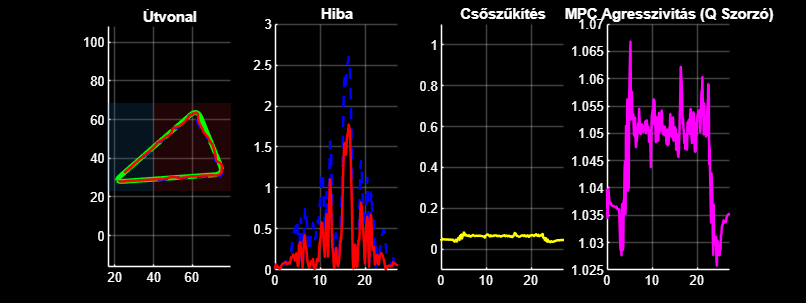

figure('Name', 'Self-Tuning AI MPC', 'Position', [50, 50, 1600, 600], 'Color', 'k');

ax1 = subplot(1, 4, 1); hold on; grid on;
patch([min(smooth_path(:,1))-5, 40, 40, min(smooth_path(:,1))-5], [min(smooth_path(:,2))-5, min(smooth_path(:,2))-5, max(smooth_path(:,2))+5, max(smooth_path(:,2))+5], [0.1 0.4 0.6], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
patch([40, max(smooth_path(:,1))+5, max(smooth_path(:,1))+5, 40], [min(smooth_path(:,2))-5, min(smooth_path(:,2))-5, max(smooth_path(:,2))+5, max(smooth_path(:,2))+5], [0.6 0.1 0.1], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
plot(smooth_path(:,1), smooth_path(:,2), '-g', 'LineWidth', 3); plot(history_cl(:,1), history_cl(:,2), 'b--', 'LineWidth', 1.5); plot(history_ai(:,1), history_ai(:,2), 'r-', 'LineWidth', 1.5);
title('Útvonal', 'Color', 'w'); axis equal; set(ax1, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');

ax2 = subplot(1, 4, 2); hold on; grid on;
plot(t_sim_test(1:n_steps_test), errors_cl, 'b--', 'LineWidth', 1.5); plot(t_sim_test(1:n_steps_test), errors_ai, 'r-', 'LineWidth', 1.5);
title('Hiba', 'Color', 'w'); set(ax2, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');

ax3 = subplot(1, 4, 3); hold on; grid on;
plot(t_sim_test(1:n_steps_test), tube_history, 'y-', 'LineWidth', 1.5); title('Csőszűkítés', 'Color', 'w'); ylim([-0.1 1.1]); set(ax3, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');

ax4 = subplot(1, 4, 4); hold on; grid on;
plot(t_sim_test(1:n_steps_test), q_mult_history, 'm-', 'LineWidth', 1.5); title('MPC Agresszivitás (Q Szorzó)', 'Color', 'w'); set(ax4, 'Color', 'k', 'XColor', 'w', 'YColor', 'w');


mean_cl = mean(errors_cl); mean_ai = mean(errors_ai);
fprintf('\n=== VÉGSŐ EREDMÉNYEK ===\nKlasszikus: %.4f m\nAI (SOTA): %.4f m\nJAVULÁS: +%.1f %%\n', mean_cl, mean_ai, (1 - (mean_ai / mean_cl)) * 100);


=== VÉGSŐ EREDMÉNYEK ===
Klasszikus: 0.5648 m
AI (SOTA): 0.3120 m
JAVULÁS: +44.8 %
